## 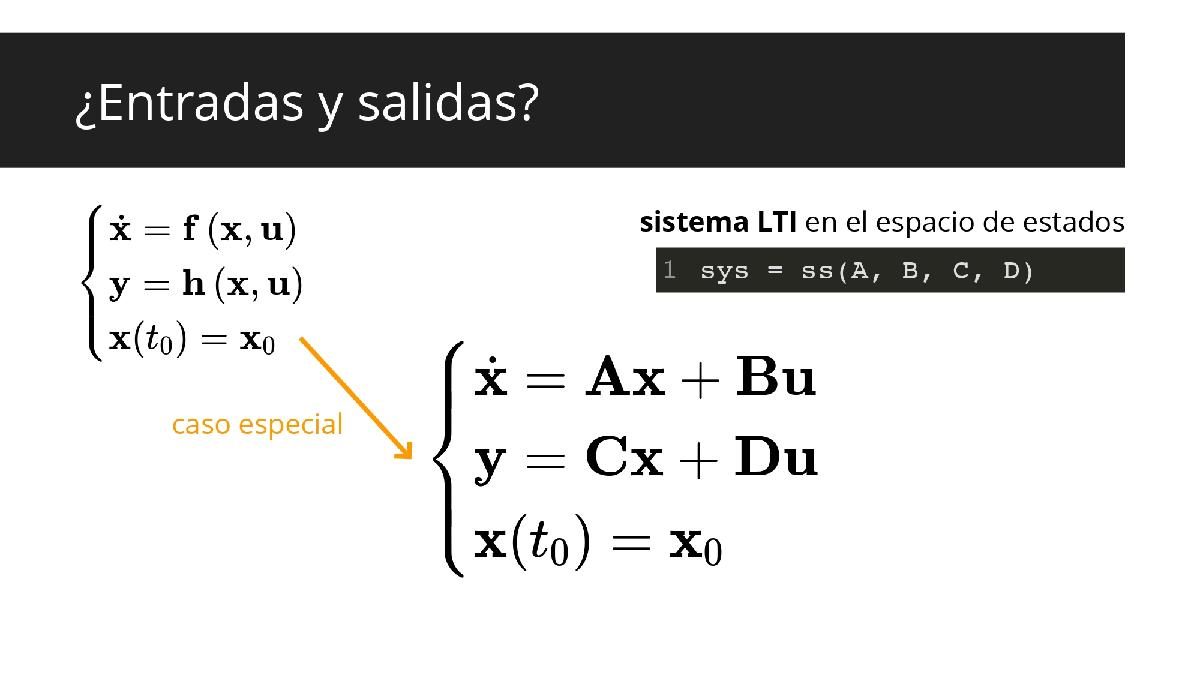

A = randn(2,2);
B = randn(2,1);
C = randn(1,2);
D = randn;

sys = ss(A, B, C, D)

sys =
 
  A = 
            x1       x2
   x1   0.8884   -1.069
   x2   -1.147  -0.8095
 
  B = 
           u1
   x1  -2.944
   x2   1.438
 
  C = 
            x1       x2
   y1   0.3252  -0.7549
 
  D = 
         u1
   y1  1.37
 
Continuous-time state-space model.



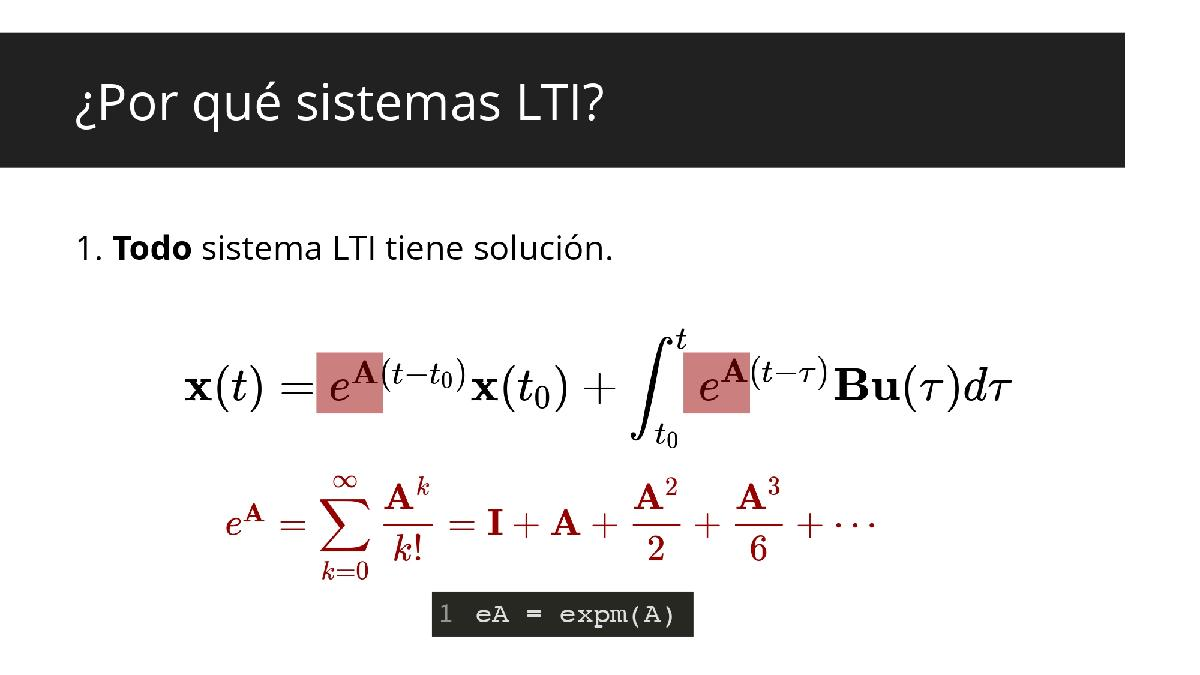

A = randn(2,2)

A =    -1.7115   -0.2414
   -0.1022    0.3192


eA = expm(A)

eA =     0.1856   -0.1427
   -0.0604    1.3856


not_eA = exp(A)

not_eA =     0.1806    0.7855
    0.9028    1.3760


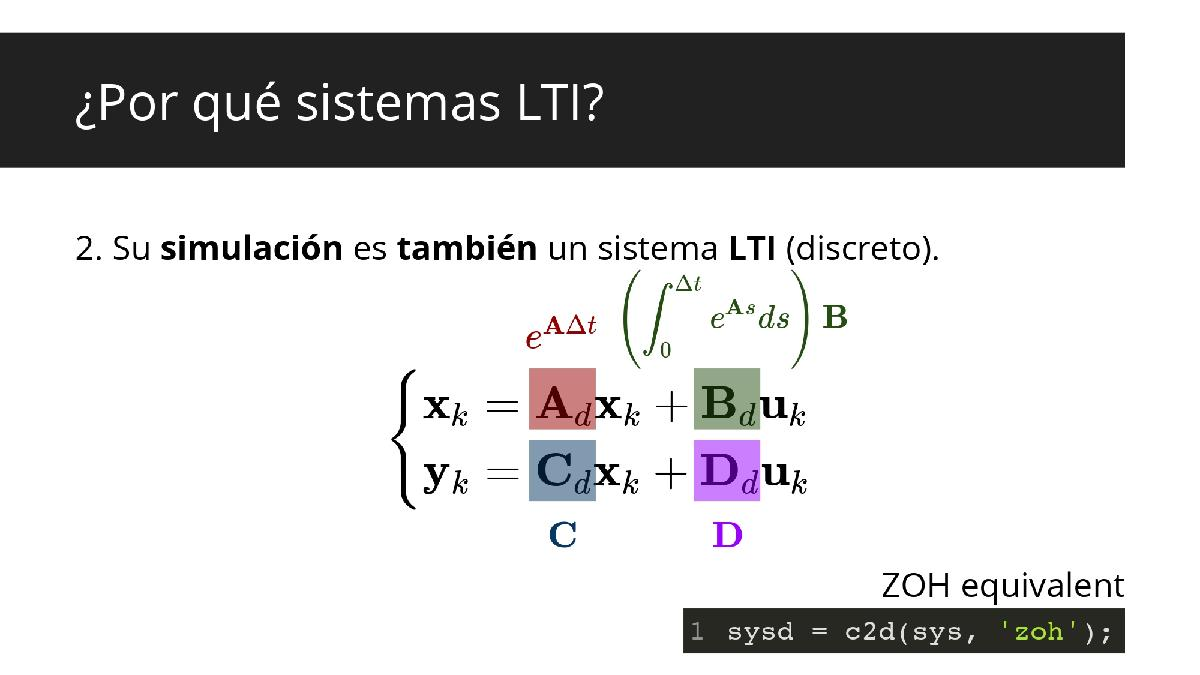

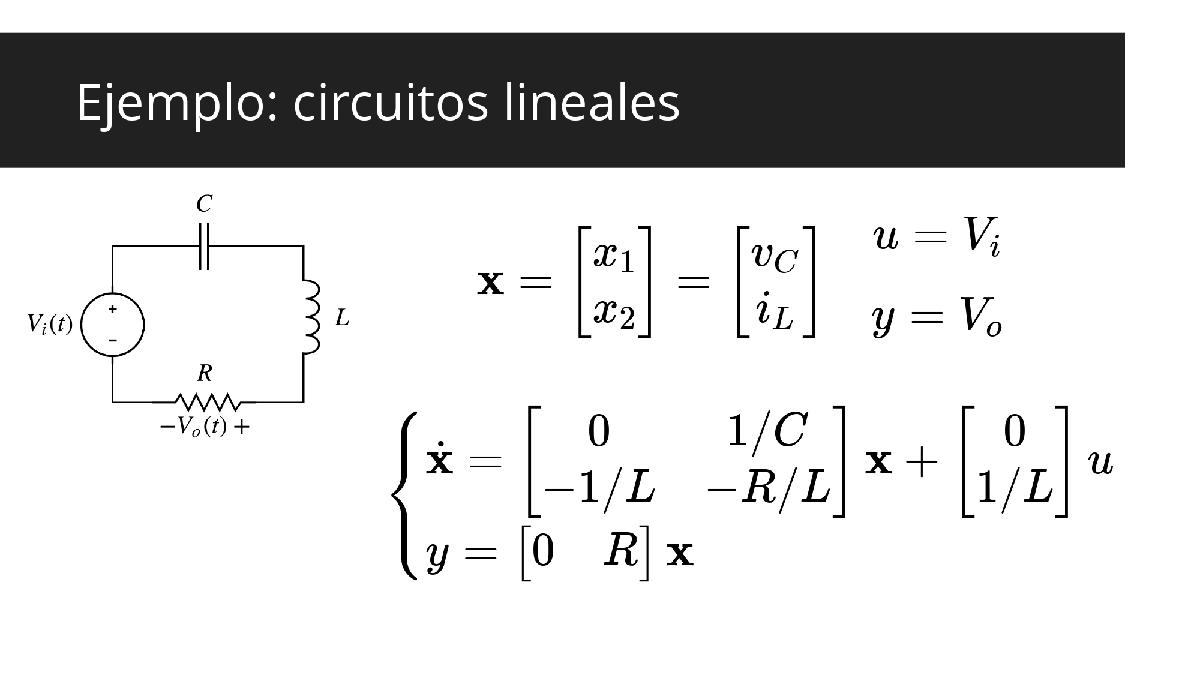

Ya habiendo obtenido el modelo del circuito podemos simularlo. Primero definimos los parámetros y las matrices del circuito:

R = 100; 
L = 1;
Cap = 10000e-6;

A = [0, 1/Cap; -1/L,-R/L];
B = [0; 1/L];
C = [0, R];

Se establecen los parámetros de la simulación:

t_0 = 0; % tiempo inicial
t_f = 10; % tiempo de simulación
dt = 0.01; % período de muestreo
K = (t_f - t_0) / dt; % número de iteraciones

x0 = [0.5; 0]; % condiciones iniciales 
u0 = 0;
y0 = C*x0;
x = x0; % vector de estado
u = u0; % entrada
y = y0; % salida

Se definen arrays auxiliares para cada una de las cantidades de importancia, ya que querremos graficar los resultados de la simulación.

% Array para almacenar las trayectorias de las variables de estado
X = zeros(numel(x0), K+1); 
X(:,1) = x;
% Array para almacenar la evolución de las entradas 
U = zeros(numel(u0), K+1); 
U(:,1) = u; 
% Array para almacenar la evolución de las salidas
Y = zeros(numel(y0), K+1); 
Y(:,1) = y; 

Se discretiza el sistema, en este caso emplearemos el equivalente ZOH:

sys = ss(A, B, C, 0); % Se define un sistema auxiliar con las matrices
sysd = c2d(sys, dt, 'zoh') % Se discretiza empleando la Toolbox

sysd =
 
  A = 
              x1         x2
   x1     0.9963     0.6311
   x2  -0.006311     0.3652
 
  B = 
             u1
   x1  0.003676
   x2  0.006311
 
  C = 
        x1   x2
   y1    0  100
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



% Se extraen las matrices del sistema discreto
Ad = sysd.A; 
Bd = sysd.B;
Cd = sysd.C;

Se hace la simulación del sistema iterando el sistema LTI discreto, dentro del ciclo podemos definir la señal de entrada que perturba al sistema.

for k = 1:K
    % Definición de la señal de entrada
    u = 1; % escalón unitario
%     u = sin(2*pi*0.1*k*dt);
    
    % Sistema LTI discreto
    x = Ad*x + Bd*u;
    y = Cd*x;
    
    % Se guardan las trayectorias del estado, entrada y salida
    X(:, k+1) = x;
    U(:, k+1) = u;
    Y(:, k+1) = y;
end

Finalmente, graficamos los resultados de la simulación:

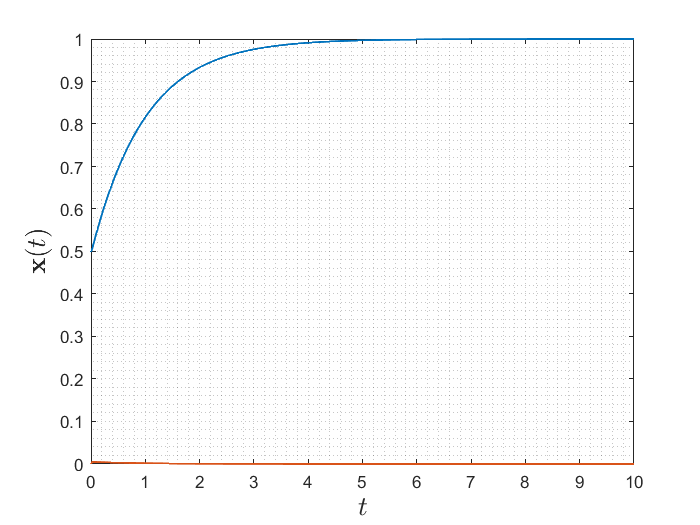

t = t_0:dt:t_f; % vector de tiempo para generar las gráficas

% Evolución de las variables de estado en el tiempo
plot(t, X', 'LineWidth', 1);
grid minor;
xlabel('$t$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$\mathbf{x}(t)$', 'Interpreter', 'latex', 'FontSize', 16);

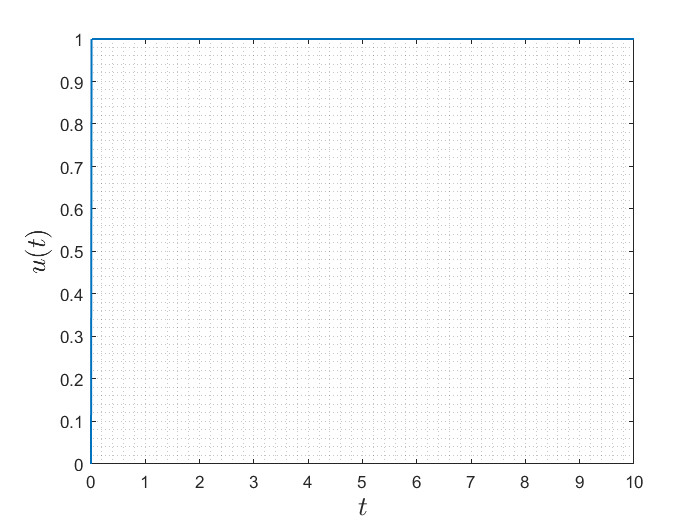


% Evolución de las entradas en el tiempo
plot(t, U', 'LineWidth', 1);
grid minor;
xlabel('$t$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$u(t)$', 'Interpreter', 'latex', 'FontSize', 16);

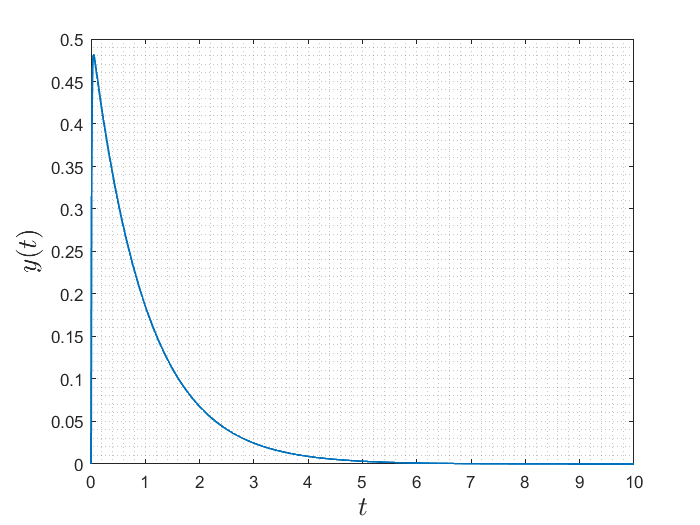


% Evolución de las salidas en el tiempo
plot(t, Y', 'LineWidth', 1);
grid minor;
xlabel('$t$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$y(t)$', 'Interpreter', 'latex', 'FontSize', 16);

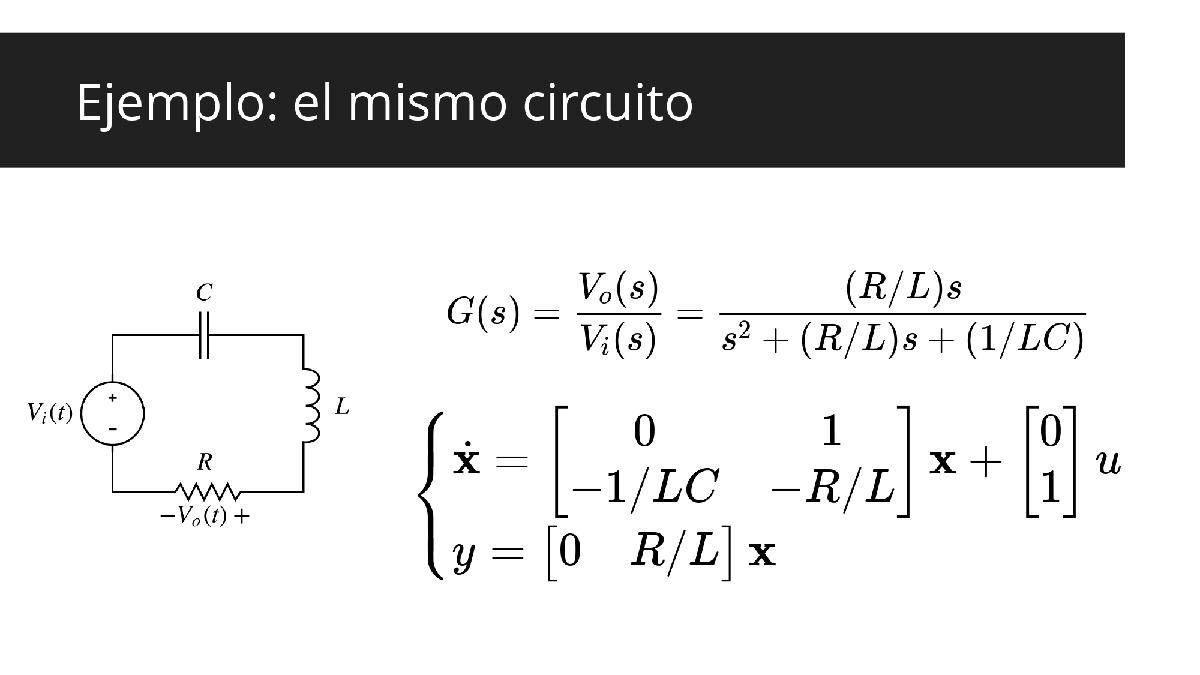

El mismo circuito presenta función de transferencia:

G = tf([R/L, 0], [1, R/L, 1/(L*Cap)])

Index in position 1 is invalid. Array indices must be positive integers or logical values.

De la cual podemos obtener la siguiente realización mínima del sistema

sysr = ss(G)

Y verificar que ambas representaciones generan la misma función de transferencia

G1 = tf(sys)
G2 = tf(sysr)